# Wyznania Religijne w Polsce – Analiza Danych Historycznych

========================================================= Dane źródłowe: GUS / Rocznik Statystyczny RP Okres: lata 1947–1998 Skrypt zawiera 15 wykresów ilustrujących liczebność i strukturę wyznań religijnych zarejestrowanych w Polsce.

Aby uruchomić jako LiveScript: otwórz w MATLAB i wybierz "Open as Live Script" lub zapisz z rozszerzeniem .mlx =========================================================

## Konfiguracja stylu wykresów

close all; clc;
set(0,'DefaultAxesFontName','Arial');
set(0,'DefaultTextFontName','Arial');
set(0,'DefaultAxesFontSize',11);

% Paleta kolorów (inspirowana Matplotlib tab10)
colors = [ ...
    0.122 0.467 0.706; ...   % niebieski
    1.000 0.498 0.055; ...   % pomarańczowy
    0.173 0.627 0.173; ...   % zielony
    0.839 0.153 0.157; ...   % czerwony
    0.580 0.404 0.741; ...   % fioletowy
    0.549 0.337 0.294; ...   % brązowy
    0.890 0.467 0.761; ...   % różowy
    0.498 0.498 0.498; ...   % szary
    0.737 0.741 0.133; ...   % żółtozielony
    0.090 0.745 0.812];      % cyjan

fprintf('Generowanie 15 wykresów...\n');

Generowanie 15 wykresów...



% =========================================================

## WYKRES 1

Polski Autokefaliczny Kościół Prawosławny Duchowni i obiekty kultu (1948–1998) =========================================================

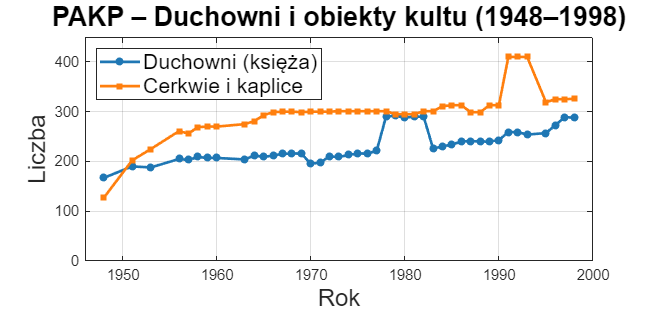

figure('Name','Wykres 1 – PAKP: Duchowni i obiekty kultu',...
    'NumberTitle','off','Units','normalized','Position',[0.05 0.55 0.45 0.38]);

pakp_duch_years = [1948,1951,1953,1956,1957,1958,1959,1960,1963,1964,1965,1966,...
    1967,1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,1980,...
    1981,1982,1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,1995,...
    1996,1997,1998];
pakp_duch_vals = [167,190,188,205,203,209,207,207,204,212,209,212,215,216,216,...
    195,198,210,209,213,216,216,221,290,292,288,290,290,226,230,234,240,241,...
    240,240,243,259,259,254,257,273,289,288];
pakp_obj_vals  = [127,202,225,261,256,269,270,270,275,281,293,299,300,300,299,...
    300,300,300,301,301,301,301,301,301,295,295,295,301,301,311,313,313,299,...
    299,313,313,410,410,410,319,325,325,326];

plot(pakp_duch_years, pakp_duch_vals, '-o', 'Color', colors(1,:), ...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(1,:));
hold on;
plot(pakp_duch_years, pakp_obj_vals, '-s', 'Color', colors(2,:), ...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(2,:));
title('PAKP – Duchowni i obiekty kultu (1948–1998)',...
    'FontSize',20,'FontWeight','bold');
xlabel('Rok', FontSize=18); ylabel('Liczba', Fontsize=18);
legend({'Duchowni (księża)','Cerkwie i kaplice'},'Location','northwest', FontSize=16);
grid on; box on; xlim([1946 2000]); ylim([0 450]);
xticks(1950:10:2000);


% =========================================================

## WYKRES 2

PAKP – Parafie i duchowni (wykres dwuosiowy) =========================================================

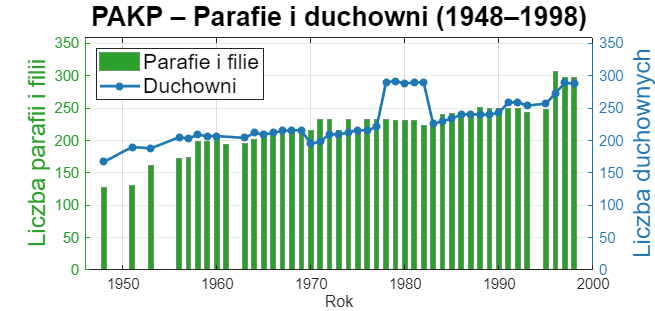

figure('Name','Wykres 2 – PAKP: Parafie i duchowni',...
    'NumberTitle','off','Units','normalized','Position',[0.52 0.55 0.45 0.38]);

pakp_par_years = [1948,1951,1953,1956,1957,1958,1959,1960,1961,1963,1964,1965,...
    1966,1967,1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,...
    1980,1981,1982,1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,...
    1995,1996,1997,1998];
pakp_par_vals  = [127,131,162,173,174,198,199,201,194,195,201,206,215,216,216,...
    215,215,233,233,215,233,215,233,233,233,231,231,231,223,223,240,242,242,...
    243,251,250,250,250,250,243,248,307,297,297];

ax = axes;

yyaxis left;
bar(pakp_par_years, pakp_par_vals, 0.5, 'FaceColor', colors(3,:),...
    'EdgeColor', [0.4 0.6 0.4]);
ylabel('Liczba parafii i filii', fontsize=18, color=colors(3,:));
ylim([0 360]);
yyaxis right;

plot(pakp_duch_years, pakp_duch_vals, '-o', 'Color', colors(1,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(1,:));
ylabel('Liczba duchownych', fontsize=18, color=colors(1,:));
ylim([0 360]);
title('PAKP – Parafie i duchowni (1948–1998)','FontSize',20,'FontWeight','bold');
xlabel('Rok'); grid on; box on;
xlim([1946 2000]); xticks(1950:10:2000);
ax.YAxis(1).Color = colors(3,:); ax.YAxis(2).Color = colors(1,:);
legend({'Parafie i filie','Duchowni'},'Location','northwest', fontsize=16);


% =========================================================

## WYKRES 3

Muzułmański Związek Religijny – liczba członków (1947–1995) =========================================================

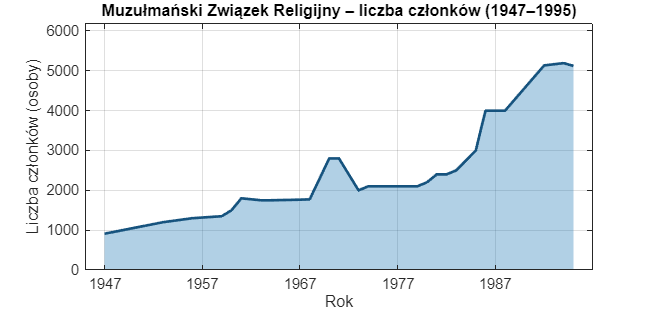

figure('Name','Wykres 3 – MZR: Liczba członków',...
    'NumberTitle','off','Units','normalized','Position',[0.05 0.08 0.45 0.38]);

mzr_czl_years = [1947,1953,1956,1959,1960,1961,1963,1964,1966,1967,1968,1970,...
    1971,1973,1974,1975,1976,1977,1978,1979,1980,1981,1982,1983,1985,1986,...
    1987,1988,1992,1994,1995];
mzr_czl_vals  = [911,1200,1300,1350,1500,1800,1750,1750,1760,1765,1773,2800,...
    2800,2000,2100,2100,2100,2100,2100,2100,2200,2400,2400,2500,3000,4000,...
    4000,4000,5135,5193,5123];

area(mzr_czl_years, mzr_czl_vals, 'FaceColor', colors(1,:),...
    'FaceAlpha',0.35,'EdgeColor',colors(1,:)*0.7,'LineWidth',2);
title('Muzułmański Związek Religijny – liczba członków (1947–1995)',...
    'FontSize',20,'FontWeight','bold');
xlabel('Rok', 'FontSize', 18); ylabel('Liczba członków (osoby)', fontsize = 18);
grid on; box on; xlim([1945 1997]); ylim([0 6200]);
xticks(1947:10:1995);

%yline(2000,'--','Color',[0.5 0.5 0.5],'Label','2 000 osób','LabelHorizontalAlignment','left');

% =========================================================

## WYKRES 4

Wyznania islamskie – struktura członkostwa (~1995) =========================================================

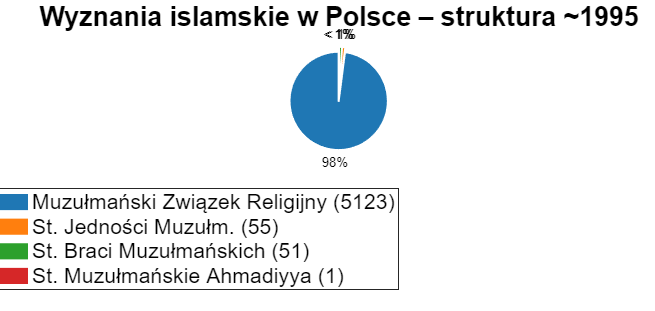

figure('Name','Wykres 4 – Islam: Struktura organizacyjna ~1995',...
    'NumberTitle','off','Units','normalized','Position',[0.52 0.08 0.45 0.38]);

islam_labels = {'Muzułmański Związek Religijny (5123)','St. Jedności Muzułm. (55)',...
    'St. Braci Muzułmańskich (51)','St. Muzułmańskie Ahmadiyya (1)'};
islam_vals   = [5123, 55, 51, 1];
explode = [1 0 0 0];
pie_h = pie(islam_vals, explode);
for k = 1:2:length(pie_h)-1
    pie_h(k).FaceColor = colors((k+1)/2,:);
    pie_h(k).EdgeColor = 'white';
    pie_h(k).LineWidth = 1.5;
end
title('Wyznania islamskie w Polsce – struktura ~1995',...
    'FontSize',20,'FontWeight','bold');
legend(islam_labels,'Location','southoutside','FontSize',16);


% =========================================================

## WYKRES 5

ZGWZ – Liczba członków i synagog (1951–1996) =========================================================

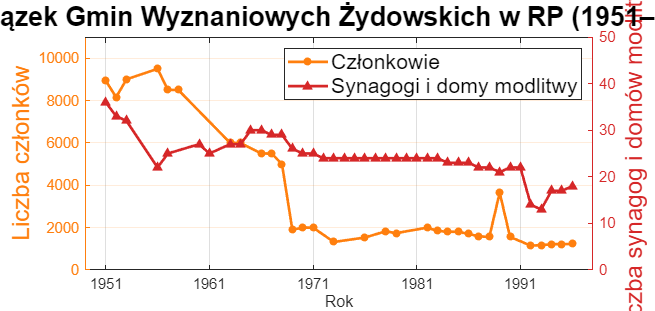

figure('Name','Wykres 5 – Judaizm: Członkowie i synagogi',...
    'NumberTitle','off','Units','normalized','Position',[0.05 0.55 0.45 0.38]);

zgwz_czl_years = [1951,1952,1953,1956,1957,1958,1963,1964,1966,1967,1968,1969,...
    1970,1971,1973,1976,1978,1979,1982,1983,1984,1985,1986,1987,1988,1989,...
    1990,1992,1993,1994,1995,1996];
zgwz_czl_vals  = [8941,8157,9000,9500,8500,8500,6000,6000,5500,5500,5000,1900,...
    2000,2000,1323,1533,1827,1739,2000,1846,1805,1805,1702,1590,1560,3650,...
    1560,1153,1170,1220,1222,1229];
zgwz_syn_years = [1951,1952,1953,1956,1957,1960,1961,1963,1964,1965,1966,1967,...
    1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,1980,1981,...
    1982,1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,1994,1995,1996];
zgwz_syn_vals  = [36,33,32,22,25,27,25,27,27,30,30,29,29,26,25,25,24,24,24,...
    24,24,24,24,24,24,24,24,24,23,23,23,22,22,21,22,22,14,13,17,17,18];

ax = axes;

yyaxis left;
plot(zgwz_czl_years, zgwz_czl_vals, '-o', 'Color', colors(2,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(2,:));
ylabel('Liczba członków', fontsize=18);
ylim([0 11000]);
yyaxis right;
plot(zgwz_syn_years, zgwz_syn_vals, '-^', 'Color', colors(4,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(4,:));
ylabel('Liczba synagog i domów modlitwy', fontsize=18);
ylim([0 50]);
title('Związek Gmin Wyznaniowych Żydowskich w RP (1951–1996)',...
    'FontSize',12,'FontWeight','bold', fontsize=20);
xlabel('Rok'); grid on; box on;
xlim([1949 1998]); xticks(1951:10:1998);
legend({'Członkowie','Synagogi i domy modlitwy'},'Location','northeast', fontsize=16); 
ax.YAxis(1).Color = colors(2,:); ax.YAxis(2).Color = colors(4,:);


% =========================================================

## WYKRES 6

Kościół Katolicki Mariawitów – liczba członków i duchownych (1948–1998) =========================================================

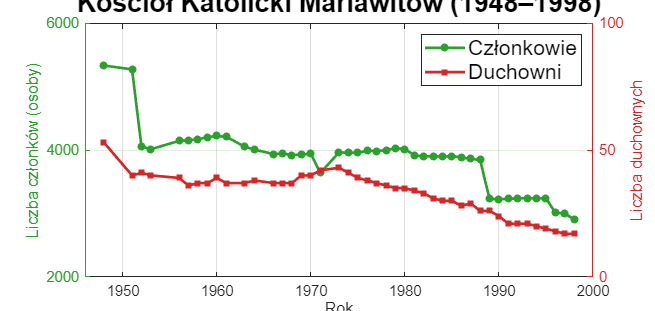

figure('Name','Wykres 6 – Mariawitów: Członkowie i duchowni',...
    'NumberTitle','off','Units','normalized','Position',[0.52 0.55 0.45 0.38]);

kkm_czl_years = [1948,1951,1952,1953,1956,1957,1958,1959,1960,1961,1963,1964,...
    1966,1967,1968,1969,1970,1971,1973,1974,1975,1976,1977,1978,1979,1980,...
    1981,1982,1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,1994,...
    1995,1996,1997,1998];
kkm_czl_vals  = [5330,5270,4059,4012,4144,4154,4167,4202,4221,4209,4051,4007,...
    3937,3944,3920,3927,3945,3639,3961,3959,3954,3991,3984,3998,4029,4015,...
    3918,3898,3904,3895,3903,3884,3860,3843,3232,3224,3232,3237,3244,3237,...
    3242,3011,3003,2904];
kkm_duch_vals = [53,40,41,40,39,36,37,37,39,37,37,38,37,37,37,40,40,42,43,...
    41,39,38,37,36,35,35,34,33,31,30,30,28,29,26,26,24,21,21,21,20,19,18,...
    17,17];

[ax,h1,h2] = plotyy(kkm_czl_years, kkm_czl_vals, kkm_czl_years, kkm_duch_vals);
h1.LineWidth = 2; h1.Color = colors(3,:);
h1.Marker = 'o'; h1.MarkerSize = 4; h1.MarkerFaceColor = colors(3,:);
h2.LineWidth = 2; h2.Color = colors(4,:);
h2.Marker = 's'; h2.MarkerSize = 4; h2.MarkerFaceColor = colors(4,:);
ax(1).YLabel.String = 'Liczba członków (osoby)';
ax(2).YLabel.String = 'Liczba duchownych';
ax(1).YColor = colors(3,:);
ax(2).YColor = colors(4,:);
title('Kościół Katolicki Mariawitów (1948–1998)','FontSize',20,'FontWeight','bold');
xlabel('Rok');
grid(ax(1),'on'); box(ax(1),'on');
xlim(ax(1),[1946 2000]); xlim(ax(2),[1946 2000]);
xticks(ax(1),1950:10:2000);
legend([h1,h2],{'Członkowie','Duchowni'},'Location','northeast', 'FontSize', 16);


% =========================================================

## WYKRES 7

Kościół Polskokatolicki – duchowni i obiekty kultu (1951–1998) =========================================================

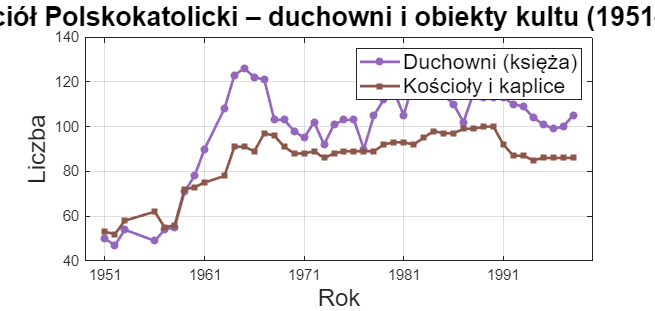

figure('Name','Wykres 7 – K. Polskokatolicki: Duchowni i obiekty',...
    'NumberTitle','off','Units','normalized','Position',[0.05 0.08 0.45 0.38]);

kpk_duch_years = [1951,1952,1953,1956,1957,1958,1959,1960,1961,1963,1964,1965,...
    1966,1967,1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,...
    1980,1981,1982,1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,...
    1994,1995,1996,1997,1998];
kpk_duch_vals  = [50,47,54,49,54,55,71,78,90,108,123,126,122,121,103,103,98,...
    95,102,92,101,103,103,90,105,112,116,105,121,116,116,114,110,102,115,...
    113,113,113,110,109,104,101,99,100,105];
kpk_obj_vals   = [53,52,58,62,55,56,72,73,75,78,91,91,89,97,96,91,88,88,89,...
    86,88,89,89,89,89,92,93,93,92,95,98,97,97,99,99,100,100,92,87,87,85,...
    86,86,86,86];

plot(kpk_duch_years, kpk_duch_vals, '-o', 'Color', colors(5,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(5,:));
hold on;
plot(kpk_duch_years, kpk_obj_vals, '-s', 'Color', colors(6,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(6,:));
title('Kościół Polskokatolicki – duchowni i obiekty kultu (1951–1998)',...
    'FontSize',20,'FontWeight','bold');
xlabel('Rok', fontsize=18); ylabel('Liczba', fontsize=18);
legend({'Duchowni (księża)','Kościoły i kaplice'},'Location','northeast', fontsize=16);
grid on; box on; xlim([1949 2000]);
xticks(1951:10:2000);


% =========================================================

## WYKRES 8

Porównanie duchownych w 3 kościołach starokatolickich (1948–1998) =========================================================

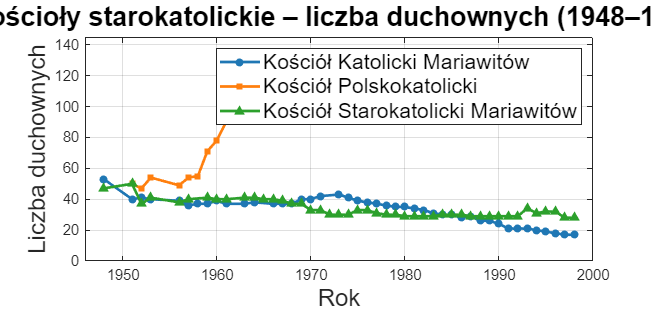

figure('Name','Wykres 8 – Kościoły starokatolickie: Duchowni',...
    'NumberTitle','off','Units','normalized','Position',[0.52 0.08 0.45 0.38]);

ksm_duch_years = [1948,1951,1952,1953,1956,1957,1959,1960,1961,1963,1964,1965,...
    1966,1967,1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,...
    1980,1981,1982,1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,...
    1994,1995,1996,1997,1998];
ksm_duch_vals  = [47,50,37,41,38,40,41,40,40,41,41,40,40,39,37,37,33,33,30,...
    30,30,33,33,31,30,30,29,29,29,29,30,30,30,29,29,29,29,29,29,34,31,32,...
    32,28,28];

plot(kkm_czl_years, kkm_duch_vals, '-o', 'Color', colors(1,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(1,:));
hold on;
plot(kpk_duch_years, kpk_duch_vals, '-s', 'Color', colors(2,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(2,:));
plot(ksm_duch_years, ksm_duch_vals, '-^', 'Color', colors(3,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(3,:));
title('Kościoły starokatolickie – liczba duchownych (1948–1998)',...
    'FontSize',20,'FontWeight','bold');
xlabel('Rok',fontsize=18); ylabel('Liczba duchownych',fontsize=18);
legend({'Kościół Katolicki Mariawitów','Kościół Polskokatolicki',...
    'Kościół Starokatolicki Mariawitów'},'Location','northeast','FontSize',16);
grid on; box on; xlim([1946 2000]);
xticks(1950:10:2000); ylim([0 145]);


% =========================================================

## WYKRES 9

Kościół Adwentystów Dnia Siódmego – liczba członków i trend (1948–1998) =========================================================

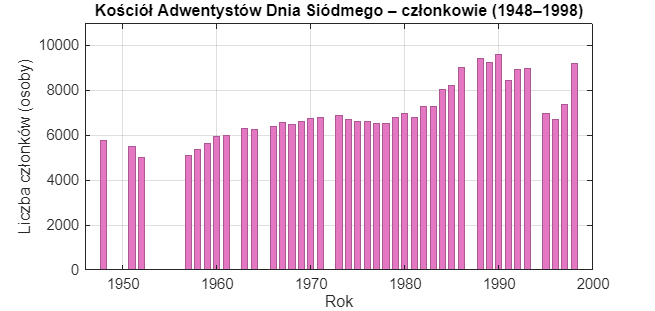

figure('Name','Wykres 9 – Adwentyści: Liczba członków',...
    'NumberTitle','off','Units','normalized','Position',[0.05 0.55 0.45 0.38]);

adw_czl_years = [1948,1951,1952,1957,1958,1959,1960,1961,1963,1964,1966,1967,...
    1968,1969,1970,1971,1973,1974,1975,1976,1977,1978,1979,1980,1981,1982,...
    1983,1984,1985,1986,1988,1989,1990,1991,1992,1993,1995,1996,1997,1998];
adw_czl_vals  = [5781,5488,5005,5105,5378,5642,5926,5988,6309,6235,6411,6586,...
    6500,6620,6750,6800,6901,6700,6630,6600,6505,6530,6794,6963,6809,7289,...
    7289,8060,8229,8997,9398,9236,9618,8418,8915,8963,6958,6720,7389,9189];

bar(adw_czl_years, adw_czl_vals, 0.65, 'FaceColor', colors(7,:),...
    'EdgeColor', colors(7,:)*0.75);
hold on;
p = polyfit(adw_czl_years - mean(adw_czl_years), adw_czl_vals, 2);
title('Kościół Adwentystów Dnia Siódmego – członkowie (1948–1998)',...
    'FontSize',20,'FontWeight','bold');
xlabel('Rok'); ylabel('Liczba członków (osoby)');
grid on; box on; xlim([1946 2000]); ylim([0 11000]);
xticks(1950:10:2000);


% =========================================================

## WYKRES 10

Kościół Chrześcijan Baptystów – 3 wskaźniki w czasie (1948–1998) =========================================================

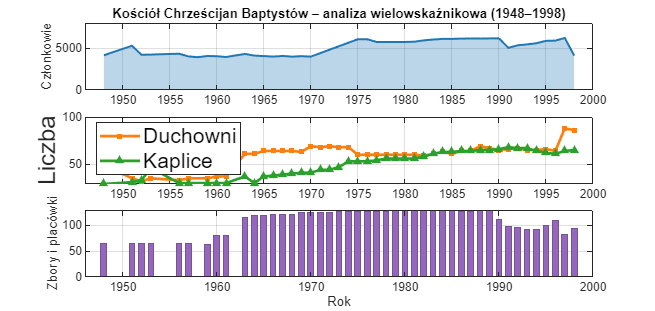

figure('Name','Wykres 10 – Baptyści: Analiza wielowskaźnikowa',...
    'NumberTitle','off','Units','normalized','Position',[0.52 0.55 0.45 0.38]);

bapt_czl_years = [1948,1951,1952,1953,1956,1957,1958,1959,1960,1961,1963,1964,...
    1966,1967,1968,1969,1970,1975,1976,1977,1978,1979,1980,1981,1982,1983,...
    1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,1994,1995,1996,1997,1998];
bapt_czl_vals  = [4146,5284,4206,4230,4334,4007,3920,4060,4033,3943,4305,4110,...
    3986,4065,3984,4040,3984,6061,6061,5734,5734,5734,5734,5765,5925,6023,...
    6103,6103,6140,6146,6146,6157,6174,5037,5340,5447,5589,5870,5894,6218,4107];
bapt_duch_years = [1948,1951,1952,1953,1956,1957,1959,1960,1961,1963,1964,1965,...
    1966,1967,1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,...
    1980,1981,1982,1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,...
    1994,1995,1996,1997,1998];
bapt_duch_vals = [49,35,32,35,33,35,35,37,37,61,61,64,64,64,64,63,69,68,69,...
    68,68,60,60,60,60,60,60,60,59,61,63,61,64,64,69,67,65,66,67,65,65,66,...
    64,88,86];
bapt_obj_vals  = [29,31,33,46,30,30,30,30,30,37,30,37,38,39,40,41,41,44,44,...
    47,53,53,53,54,56,56,56,56,58,61,63,63,64,64,65,65,66,68,67,67,64,62,...
    61,64,65];
bapt_jed_vals  = [64,64,64,64,64,64,63,79,79,114,119,119,121,121,121,124,...
    124,125,125,127,127,127,127,127,127,128,128,128,128,129,129,128,127,127,...
    128,129,111,98,95,92,92,100,109,82,94];


subplot(3,1,1);
area(bapt_czl_years, bapt_czl_vals, 'FaceColor', colors(1,:),...
    'FaceAlpha',0.3,'EdgeColor',colors(1,:),'LineWidth',1.5);
ylabel('Członkowie', FontSize=18); grid on; box on; xlim([1946 2000]); ylim([0 8000]);
title('Kościół Chrześcijan Baptystów – analiza wielowskaźnikowa (1948–1998)',...
    'FontSize',20,'FontWeight','bold');

subplot(3,1,2);
plot(bapt_duch_years, bapt_duch_vals, '-s', 'Color', colors(2,:),...
    'LineWidth',2,'MarkerSize',3,'MarkerFaceColor',colors(2,:));
hold on;
plot(bapt_duch_years, bapt_obj_vals, '-^', 'Color', colors(3,:),...
    'LineWidth',2,'MarkerSize',3,'MarkerFaceColor',colors(3,:));
ylabel('Liczba', FontSize=18); legend({'Duchowni','Kaplice'},'Location','northwest','FontSize',16);
grid on; box on; xlim([1946 2000]);

subplot(3,1,3);
bar(bapt_duch_years, bapt_jed_vals, 0.6, 'FaceColor', colors(5,:),...
    'EdgeColor', colors(5,:)*0.8);
ylabel('Zbory i placówki', FontSize=18); xlabel('Rok', FontSize=18);
grid on; box on; xlim([1946 2000]);
xticks(1950:10:2000);


% =========================================================

## WYKRES 11

Kościół Ewangelicko-Augsburski – duchowni i kościoły (1948–1998) =========================================================

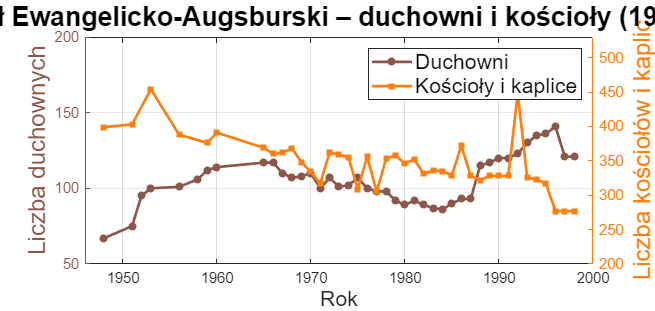

figure('Name','Wykres 11 – K.E. Augsburski: Duchowni i kościoły',...
    'NumberTitle','off','Units','normalized','Position',[0.05 0.08 0.45 0.38]);

kea_d_years = [1948,1951,1952,1953,1956,1958,1959,1960,1965,1966,1967,1968,...
    1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,1980,1981,1982,...
    1983,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,1994,1995,1996,...
    1997,1998];
kea_d_vals  = [67,75,95,100,101,106,112,114,117,117,110,107,108,110,100,107,...
    101,102,107,100,98,98,92,89,92,89,87,86,90,93,93,115,117,120,120,123,...
    130,135,136,141,121,121];
kea_o_years = [1948,1951,1953,1956,1959,1960,1965,1966,1967,1968,1969,1970,...
    1971,1972,1973,1974,1975,1976,1977,1978,1979,1980,1981,1982,1983,1984,...
    1985,1986,1987,1988,1989,1990,1991,1992,1993,1994,1995,1996,1997,1998];
kea_o_vals  = [399,403,454,388,376,391,369,360,362,368,348,334,317,362,359,...
    355,309,356,305,353,358,346,352,331,336,335,329,372,328,322,328,328,...
    328,448,326,323,317,277,277,277];

ax = axes;

yyaxis left;
plot(kea_d_years, kea_d_vals, '-o', 'Color', colors(6,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(6,:));
ylabel('Liczba duchownych', 'FontSize', 18);
ylim([50 200]);
yyaxis right;
plot(kea_o_years, kea_o_vals, '-s', 'Color', colors(2,:),...
    'LineWidth',2,'MarkerSize',4,'MarkerFaceColor',colors(2,:));
ylabel('Liczba kościołów i kaplic', 'FontSize', 18);
ylim([200 530]);
title('Kościół Ewangelicko-Augsburski – duchowni i kościoły (1948–1998)',...
    'FontSize',20,'FontWeight','bold');
xlabel('Rok', 'FontSize', 16); grid on; box on; xlim([1946 2000]);
xticks(1950:10:2000);
legend({'Duchowni','Kościoły i kaplice'},'Location','northeast', 'FontSize', 16);
ax.YAxis(1).Color = colors(6,:); ax.YAxis(2).Color = colors(2,:);


% =========================================================

## WYKRES 12

Top 8 wyznań protestanckich w Polsce – liczba członków (1998) =========================================================

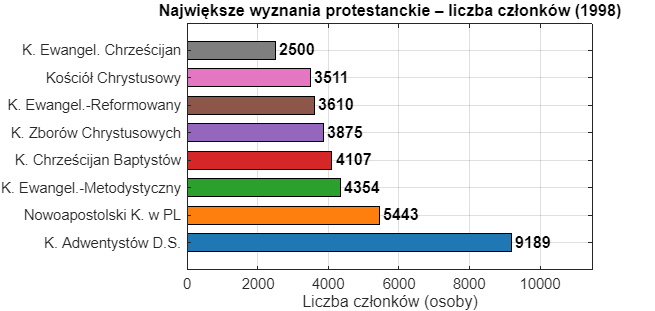

figure('Name','Wykres 12 – Protestanci: Ranking 1998',...
    'NumberTitle','off','Units','normalized','Position',[0.52 0.08 0.45 0.38]);

prot_names   = {'K. Adwentystów D.S.','Nowoapostolski K. w PL','K. Ewangel.-Metodystyczny',...
    'K. Chrześcijan Baptystów','K. Zborów Chrystusowych','K. Ewangel.-Reformowany',...
    'Kościół Chrystusowy','K. Ewangel. Chrześcijan'};
prot_m_1998  = [9189, 5443, 4354, 4107, 3875, 3610, 3511, 2500];

hb = barh(1:8, prot_m_1998, 0.65, 'FontSize', 18);
hb.FaceColor = 'flat';
for k = 1:8
    hb.CData(k,:) = colors(mod(k-1,10)+1,:);
end
yticks(1:8); yticklabels(prot_names); ylim([0 9]);
xlabel('Liczba członków (osoby)', 'FontSize', 18);
title('Największe wyznania protestanckie – liczba członków (1998)',...
    'FontSize',20,'FontWeight','bold');
grid on; box on; xlim([0 11500]);
for k = 1:8
    text(prot_m_1998(k)+100, k, num2str(prot_m_1998(k)),...
        'VerticalAlignment','middle', 'FontSize', 12,'FontWeight','bold');
end


% =========================================================

## WYKRES 13

Wyznania Dalekiego Wschodu – łączna liczba członków (1981–1998) =========================================================

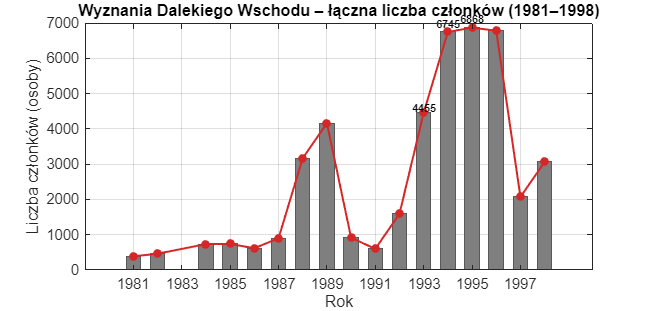

figure('Name','Wykres 13 – Daleki Wschód: Łączna liczba członków',...
    'NumberTitle','off','Units','normalized','Position',[0.05 0.55 0.45 0.38]);

dw_years = [1981,1982,1984,1985,1986,1987,1988,1989,1990,1991,1992,1993,...
    1994,1995,1996,1997,1998];
dw_vals  = [387,462,735,737,617,899,3169,4158,914,599,1592,4455,...
    6745,6868,6782,2069,3062];

bar(dw_years, dw_vals, 0.6, 'FaceColor', colors(8,:), 'EdgeColor', colors(8,:)*0.7);
hold on;
plot(dw_years, dw_vals, '-o', 'Color', colors(4,:),...
    'LineWidth',1.5,'MarkerSize',5,'MarkerFaceColor',colors(4,:));
title('Wyznania Dalekiego Wschodu – łączna liczba członków (1981–1998)',...
    'FontSize',12,'FontWeight','bold');
xlabel('Rok'); ylabel('Liczba członków (osoby)');
grid on; box on; xlim([1979 2000]);
xticks(1981:2:1998);
% Adnotacje przy szczytach
text(1993, 4600, '4455', 'FontSize',8,'HorizontalAlignment','center','FontWeight','bold');
text(1994, 6960, '6745', 'FontSize',8,'HorizontalAlignment','center','FontWeight','bold');
text(1995, 7100, '6868', 'FontSize',8,'HorizontalAlignment','center','FontWeight','bold');


% =========================================================

## WYKRES 14

MZR – liczba meczetów i liczba członków (1947–1995) =========================================================

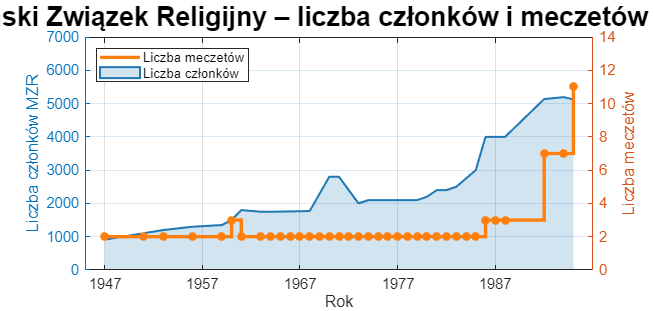

figure('Name','Wykres 14 – MZR: Meczety i członkowie',...
    'NumberTitle','off','Units','normalized','Position',[0.52 0.55 0.45 0.38]);

mzr_obj_years = [1947,1951,1953,1956,1959,1960,1961,1963,1964,1965,1966,1967,...
    1968,1969,1970,1971,1972,1973,1974,1975,1976,1977,1978,1979,1980,1981,...
    1982,1983,1984,1985,1986,1987,1988,1992,1994,1995];
mzr_obj_vals  = [2,2,2,2,2,3,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,...
    2,2,3,3,3,7,7,11];

yyaxis left;
area(mzr_czl_years, mzr_czl_vals, 'FaceColor', colors(1,:),...
    'FaceAlpha',0.2,'EdgeColor',colors(1,:),'LineWidth',1.5);
ylabel('Liczba członków MZR');
ylim([0 7000]);
yyaxis right;
stairs(mzr_obj_years, mzr_obj_vals, 'Color', colors(2,:), 'LineWidth', 2.5);
hold on;
plot(mzr_obj_years, mzr_obj_vals, 'o', 'Color', colors(2,:),...
    'MarkerFaceColor',colors(2,:),'MarkerSize',6);
ylabel('Liczba meczetów');
ylim([0 14]);
title('Muzułmański Związek Religijny – liczba członków i meczetów (1947–1995)',...
    'FontSize',20,'FontWeight','bold');
xlabel('Rok'); grid on; box on; xlim([1945 1997]);
xticks(1947:10:1995);
legend({'Liczba członków','Liczba meczetów'},'Location','northwest');


% =========================================================

## WYKRES 15

Wskaźnik Duchowni / Obiekty kultu – porównanie wyznań (1998) =========================================================

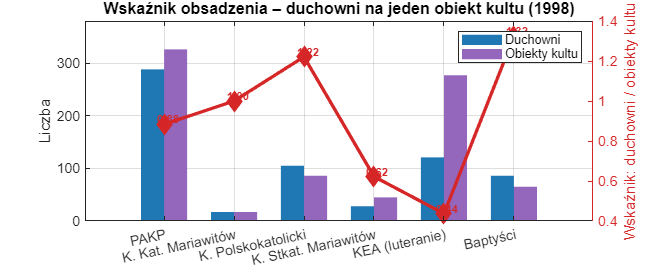

figure('Name','Wykres 15 – Wskaźnik duchowni/obiekty (1998)',...
    'NumberTitle','off','Units','normalized','Position',[0.05 0.08 0.55 0.40]);

w15_names  = {'PAKP','K. Kat. Mariawitów','K. Polskokatolicki','K. Stkat. Mariawitów','KEA (luteranie)','Baptyści'};
w15_duch   = [288, 17, 105, 28, 121, 86];
w15_obj    = [326, 17,  86, 45, 277, 65];
w15_ratio  = w15_duch ./ w15_obj;
x15 = 1:6;
bw  = 0.33;

ax = axes;

hb1 = bar(x15 - bw/2, w15_duch, bw, 'FaceColor', colors(1,:), 'EdgeColor', 'none');
hold on;
hb2 = bar(x15 + bw/2, w15_obj,  bw, 'FaceColor', colors(5,:), 'EdgeColor', 'none');
yyaxis right;
plot(x15, w15_ratio, '-d', 'Color', colors(4,:),...
    'LineWidth',2.5,'MarkerSize',9,'MarkerFaceColor',colors(4,:));
for k = 1:6
    text(x15(k)+0.05, w15_ratio(k)+0.02, sprintf('%.2f', w15_ratio(k)),...
        'FontSize',8.5,'HorizontalAlignment','center','Color',colors(4,:),...
        'FontWeight','bold');
end
ylabel('Wskaźnik: duchowni / obiekty kultu');
yyaxis left;
ylabel('Liczba');
ylim([0 380]);
xticks(x15); xticklabels(w15_names); xtickangle(12);
title('Wskaźnik obsadzenia – duchowni na jeden obiekt kultu (1998)',...
    'FontSize',12,'FontWeight','bold');
legend([hb1, hb2], {'Duchowni','Obiekty kultu'},'Location','northeast');
grid on; box on;

ax.YAxis(2).Color = colors(4,:);


% =========================================================

## Podsumowanie

=========================================================

fprintf('\n================================================\n');

fprintf('  WYZNANIA RELIGIJNE W POLSCE – 15 WYKRESÓW\n');

  WYZNANIA RELIGIJNE W POLSCE – 15 WYKRESÓW


fprintf('================================================\n');

fprintf(' Wyk.  1: PAKP – Duchowni i obiekty kultu (1948–1998)\n');

 Wyk.  1: PAKP – Duchowni i obiekty kultu (1948–1998)


fprintf(' Wyk.  2: PAKP – Parafie i duchowni (dwuosiowy)\n');

 Wyk.  2: PAKP – Parafie i duchowni (dwuosiowy)


fprintf(' Wyk.  3: MZR – Liczba członków (1947–1995)\n');

 Wyk.  3: MZR – Liczba członków (1947–1995)


fprintf(' Wyk.  4: Islam – Struktura organizacyjna (~1995)\n');

 Wyk.  4: Islam – Struktura organizacyjna (~1995)


fprintf(' Wyk.  5: Judaizm – Członkowie i synagogi (1951–1996)\n');

 Wyk.  5: Judaizm – Członkowie i synagogi (1951–1996)


fprintf(' Wyk.  6: K. Kat. Mariawitów – Członkowie i duchowni\n');

 Wyk.  6: K. Kat. Mariawitów – Członkowie i duchowni


fprintf(' Wyk.  7: K. Polskokatolicki – Duchowni i obiekty\n');

 Wyk.  7: K. Polskokatolicki – Duchowni i obiekty


fprintf(' Wyk.  8: Kościoły starokatolickie – Porównanie duchownych\n');

 Wyk.  8: Kościoły starokatolickie – Porównanie duchownych


fprintf(' Wyk.  9: Adwentyści – Liczba członków + trend\n');

 Wyk.  9: Adwentyści – Liczba członków + trend


fprintf(' Wyk. 10: Baptyści – Analiza wielowskaźnikowa\n');

 Wyk. 10: Baptyści – Analiza wielowskaźnikowa


fprintf(' Wyk. 11: KEA – Duchowni i kościoły (dwuosiowy)\n');

 Wyk. 11: KEA – Duchowni i kościoły (dwuosiowy)


fprintf(' Wyk. 12: Top 8 protestantów – Ranking 1998\n');

 Wyk. 12: Top 8 protestantów – Ranking 1998


fprintf(' Wyk. 13: Wyznania Dalekiego Wschodu – Sumaryczne\n');

 Wyk. 13: Wyznania Dalekiego Wschodu – Sumaryczne


fprintf(' Wyk. 14: MZR – Meczety i członkowie (dwuosiowy)\n');

 Wyk. 14: MZR – Meczety i członkowie (dwuosiowy)


fprintf(' Wyk. 15: Wskaźnik duchowni/obiekty – Porównanie\n');

 Wyk. 15: Wskaźnik duchowni/obiekty – Porównanie


fprintf('\nŹródło: GUS / Rocznik Statystyczny RP, dane 1947–1998\n');


Źródło: GUS / Rocznik Statystyczny RP, dane 1947–1998


fprintf('================================================\n');